A big test out of all the pieces of the motion detection code using one example stimulus.

## Main.m 

The main script that runs all the trials. This block contains all the parameters that are specified there. I comment out allPulseDelay because we won't loop through all those. 

params.subDelay = 0.05; %50 ms
params.productSubtraction = true;
params.subunitInh = false;
params.model = load('fullModelMAT'); %loads model data
params.model.excNLFuncH = params.model.excWithInfo.params.nlEvaluator;
params.model.inhNLFuncH = params.model.inhWithInfo.params.nlEvaluator;

% Stim params that I want to loop over
% allPulseDelay = 0:0.005:0.05; %[0 0.025:0.025:0.1 0.15 0.25]; %0:0.005:0.05; %[0:0.005:0.02 0.025:0.025:0.15];
params.pulseContrast = 1; % 100%

% Stimulus params
params.pulseDur = 0.01; % pulse width: 10 ms by default

params.fullInputDur = 2;%why wasn't this just shortened?
params.noiseAmountNorm = 0.1; %0.1;
params.corrlNoise = false;
params.blueMean = 10;
params.redMean = 200;
params.sampleIntrv = 1E-4; % sampling rate

% Trial params
params.respTStart = 0.9;
params.respTEnd = 1.9;
params.repeats = 5500; %number of trials per condition
params.sizeTrain = 100;
sizeTest = params.repeats - params.sizeTrain;
% params.totalSims = 3; %5 set this back when done testing 

projDiscAnalysis = false;

We'll set something for params.pulseDelay since we're not looping through many values. For this left to right stim, we'll call **generateReichardtStim**, but for the right to left we'll see what is happening inside the function. generateReichardtStim returns a struct with inputs for the left and right channels and within each there are blue and red stims for the rods and cones within each channel. Those are 5500X20000 arrays with 20000 being for time, and 5500 trials are generated here. 

params.pulseDelay = 0.02; % 20ms

% Generate stimuli
leftToRight = false;
stimLeftward = generateReichardtStim(params.pulseDur, ...
    params.pulseDelay,  params.pulseContrast, leftToRight, ...
    params.noiseAmountNorm, params.fullInputDur, params.sampleIntrv, ...
    params.redMean, params.blueMean, params.repeats, params.corrlNoise);

leftToRight = true;
stimRightward = generateReichardtStim(params.pulseDur, ...
    params.pulseDelay,  params.pulseContrast, leftToRight, ...
    params.noiseAmountNorm, params.fullInputDur, params.sampleIntrv, ...
    params.redMean, params.blueMean, params.repeats, params.corrlNoise);

Plotting it to see the first row of 5500 inputs. 

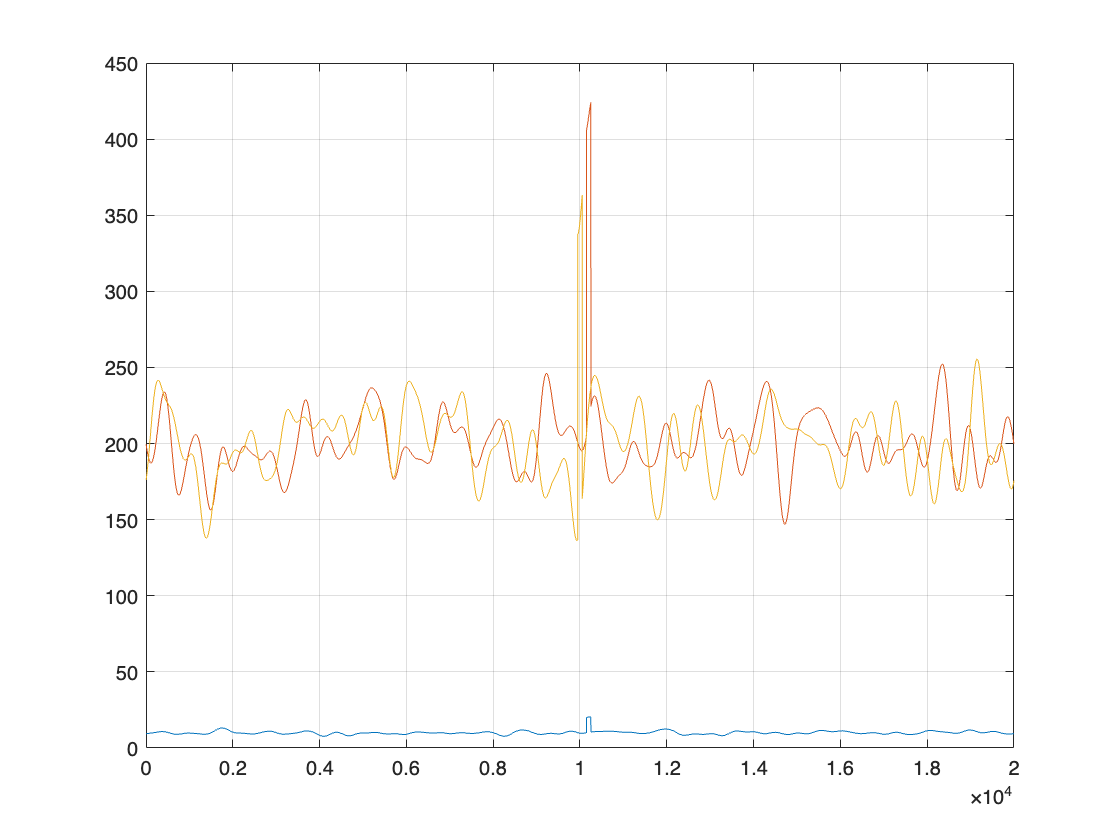

figure; plot(stimLeftward.leftStim.blue(1,:))
hold on
plot(stimLeftward.leftStim.red(1,:))
plot(stimLeftward.rightStim.red(1,:))
grid on;

## generateReichardtStim

This is most of what's in the generateReichardtStim function. Note that **generateNoiseStim** is called here. 

% Calculate some vector lengths, from inputs given in seconds
pulseLength = round(params.pulseDur / params.sampleIntrv);
delayLength = round(params.pulseDelay / params.sampleIntrv);
% pulseAndDelayLength = pulseLength + delayLength;
totalStimLength = round(params.fullInputDur / params.sampleIntrv);

% Find out how much you need to pad the motion stimuli temporally
% to get it to the specified total stimulus length (do this for both the
% left and right subunits)
bufferLength1 = (totalStimLength - pulseLength) / 2;
if (mod(bufferLength1, 2) == 0)
    bufferLength2 = bufferLength1;
else
    bufferLength1 = floor(bufferLength1);
    bufferLength2 = bufferLength1;
end
delayedBufferLength1 = bufferLength1 + delayLength;
delayedBufferLength2 = bufferLength2 - delayLength;

% Generate pulse traces for red and blue
s1.blue = setMotionTrace(bufferLength1, bufferLength2, ...
    pulseLength, params.pulseContrast, repeats, blueMean);
s2.blue = setMotionTrace(delayedBufferLength1, delayedBufferLength2, ...
    pulseLength, params.pulseContrast, repeats, blueMean);

s1.red = setMotionTrace(bufferLength1, bufferLength2, ...
    pulseLength, params.pulseContrast, repeats, redMean);
s2.red = setMotionTrace(delayedBufferLength1, delayedBufferLength2, ...
    pulseLength, params.pulseContrast, repeats, redMean);

% Add the type of noise set by the parameters
if params.noiseAmountNorm ~= 0
    
    % frequencyCutoff = 20; noiseFilterCount = 4; stimMean=0;

    % Generate a noise trace for the two different pulse stimuli
    noiseTrace1 = generateNoiseTrace(params.sampleIntrv, 20, 4, params.repeats, ...
        params.fullInputDur, 0, params.noiseAmountNorm);
    noiseTrace2 = generateNoiseTrace(params.sampleIntrv, 20, 4, params.repeats, ...
        params.fullInputDur, 0, params.noiseAmountNorm);
    
    blueNoiseTrace1 = params.blueMean .* noiseTrace1;
    blueNoiseTrace2 = params.blueMean .* noiseTrace2;
    
    if params.corrlNoise % if noise is correlated for rods and cones
        redNoiseTrace1 = params.redMean .* noiseTrace1;
        redNoiseTrace2 = params.redMean .* noiseTrace2;
    else
        % Generate another set of noise so that rod and cone is different
        noiseTraceAlt1 = generateNoiseTrace(params.sampleIntrv, 20, 4, params.repeats, ...
            params.fullInputDur, 0, params.noiseAmountNorm);
        noiseTraceAlt2 = generateNoiseTrace(params.sampleIntrv, 20, 4, params.repeats, ...
            params.fullInputDur, 0, params.noiseAmountNorm); 
        
        redNoiseTrace1 = params.redMean .* noiseTraceAlt1;
        redNoiseTrace2 = params.redMean .* noiseTraceAlt2;
        
    end
    
    % The noise model is additive (i.e. not signal dependent)?
    s1.blue = s1.blue + blueNoiseTrace1;
    s1.red = s1.red + redNoiseTrace1;
    
    s2.blue = s2.blue + blueNoiseTrace2;
    s2.red = s2.red + redNoiseTrace2;
        
end

% Designate the direction of motion
if leftToRight
    leftStim = s1;
    rightStim = s2;
else
    leftStim = s2;
    rightStim = s1;
end

rodConeReichardtStim.leftStim = leftStim;
rodConeReichardtStim.rightStim = rightStim;

### main

The next part of main calls **reichardtTrialSet**. Apparently, all the pRod variables are NaN. All that matters are the probTMeans variables (which correspond to leftBool and rightBool inside the function).

i = 1; % only 1 trial here
params.subunitType = 'separateRod';

[probTMeansL.rod(:,i), probTMeansR.rod(:,i), ...
    pRodLL, pRodLR, pRodRR, pRodRL] = ...
    reichardtTrialSet(params, stimLeftward, stimRightward);

The outputs are booleans that indicate how many trials were classified as left or right for the left and right stims. For example, probTMeansL have 1s for all the (correctly) classified leftward trials marked as left (0s for leftward trials marked as right). 

sum(probTMeansL.rod) % the number of correctly classified trials out of the 5500

ans = 4454

mean(probTMeansL.rod) % the proportion of correctly classified trials

ans = 0.8248

## reichardtTrialSet

This function calls **generateReichardtResp** and then later splits part of the trials off.

% Generate responses
respLeftward = generateReichardtResp(params.model, stimLeftward, ...
    params.subunitType, params.subunitInh, params.subDelay, ...
    params.sampleIntrv, params.productSubtraction);
respRightward = generateReichardtResp(params.model, stimRightward, ...
    params.subunitType, params.subunitInh, params.subDelay, ...
    params.sampleIntrv, params.productSubtraction);

Plot the result. respLeftward is a 5500x20000 array. I'll plot the stim for this trial on top and the rod response on the bottom. 

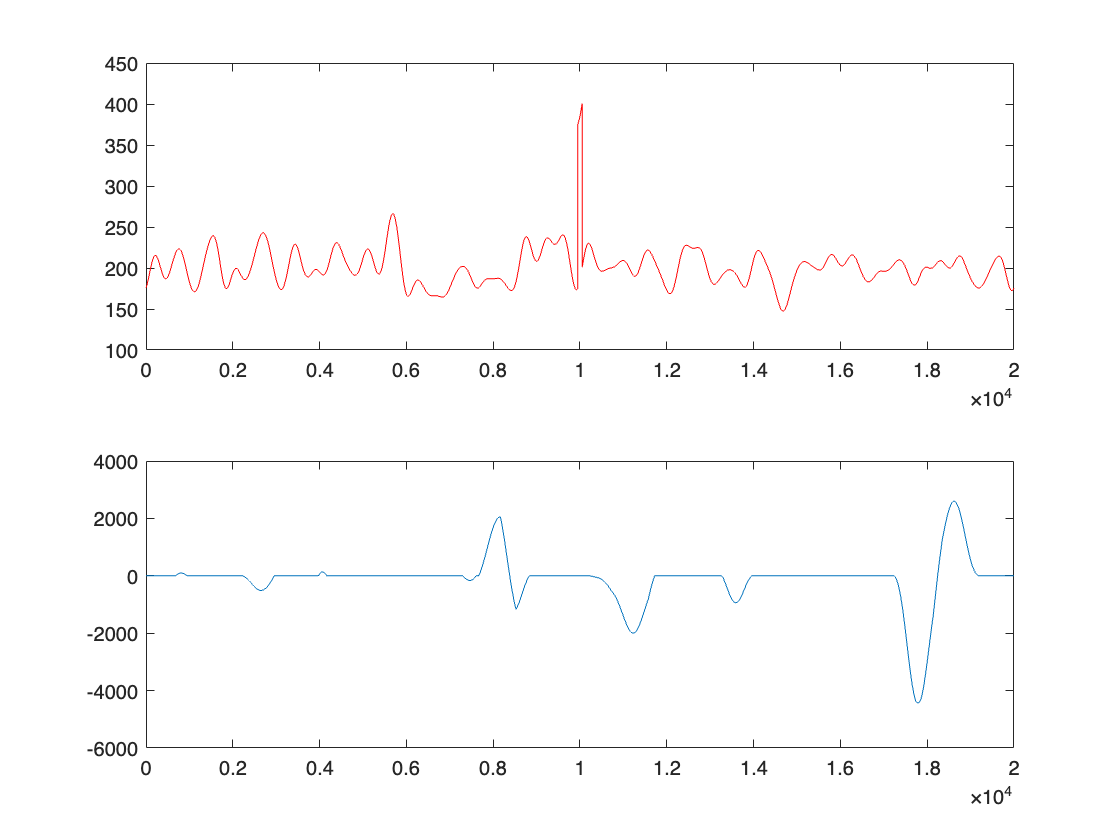

figure;
subplot(2,1,1); plot(stimLeftward.rightStim.red(1,:),'red')
subplot(2,1,2); plot(respLeftward(1,:))

## generateReichardtResp

Calls **runRodConeModel** which then calls **convolveFilterWithStim**. 

%function reichardtOut = generateReichardtResp(model, stim, subunitType, ...
    % subunitInh, subDelay, sampleIntrv, productSubtraction)
stim = stimLeftward;
model = params.model;
subunitType = params.subunitType;
subunitInh = params. subunitInh;
subDelay = params.subDelay;
sampleIntrv = params.sampleIntrv;
productSubtraction = params.productSubtraction;

% Set the stimulus struct such that it can run with the specified subunit.
if contains(subunitType, 'shared')
    leftStim.combinedRod = stim.leftStim.blue;
    leftStim.combinedCone = stim.leftStim.red;
    rightStim.combinedRod = stim.rightStim.blue;
    rightStim.combinedCone = stim.rightStim.red;

elseif strcmp(subunitType, 'separateRod')
    leftStim.rod = stim.leftStim.blue;
    rightStim.rod = stim.rightStim.blue;
    
elseif strcmp(subunitType, 'separateCone')
    leftStim.cone = stim.leftStim.red;
    rightStim.cone = stim.rightStim.red;

elseif strcmp(subunitType, 'coneShiftedCone') %
    leftStim.cone = stim.leftStim.red;
    rightStim.cone = stim.rightStim.red;

else
    leftStim.cone = stim.leftStim.red;
    rightStim.cone = stim.rightStim.red;
    
end

% Run the stimuli
[~, respL] = runRodConeModel(model.exc.filters, model.exc.nlFuncs, ...
    leftStim, subunitType, model.excNLFuncH);
[~, respR] = runRodConeModel(model.exc.filters, model.exc.nlFuncs, ...
    rightStim, subunitType, model.excNLFuncH);

Plot of filtered stim before going through the nonlinearities.

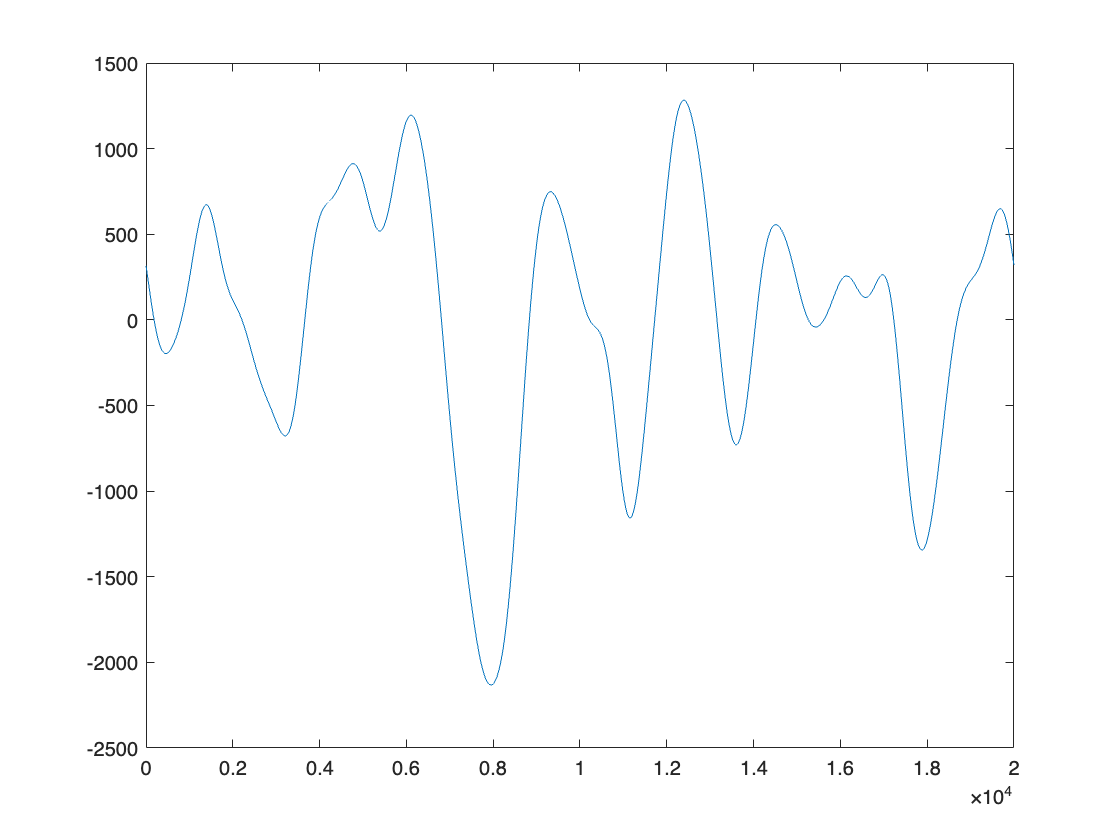

figure; plot(respL(1,:))

## runRodConeModel

This function basically takes all the stims and generates an array of responses by convolving with the filters. It calls **convolveFilterWithStim** which has to truncate or zero pad the filter and the stim to make them the same size. 

% function [output, genSig] = runRodConeModel(filters, nlFuncs, stims, ...
%     runType, nlEvaluator)

% Computes predicted responses given stimuli, filter, nonlinearity, and
% the type of forward run

% Input:
%   filters    - struct containing rod and cone filter vectors
%   stims      - struct containing rod and cone stimuli matrices
%   nlFuncs    - struct containing nonlinearity polynomial fits and scaling
%   runType    - string that's either 'sharedRod', 'sharedCone', or
%                'separateRod', 'separateCone', or 'sharedComb',
%                'separateComb'
% Output:
%   output     - a struct containing predicted current input traces
%   genSig     - a struct containing generator signal values

antiCausal = false; % ???

if strcmp(runType, 'separateRod') % rod-only
    genSig = convolveFilterWithStim(filters.rod, stims.rod, antiCausal);
    output = passToNonlinearity(genSig, nlEvaluator, nlFuncs.rod);

elseif strcmp(runType, 'separateCone') % cone-only
    genSig = convolveFilterWithStim(filters.cone, stims.cone, antiCausal);
    output = passToNonlinearity(genSig, nlEvaluator, nlFuncs.cone);

elseif strcmp(runType, 'separateComb') %rod and cone pass through NL before being combined
    gsRod = convolveFilterWitheStim(filters.rod, stims.combinedRod, antiCausal);
    gsCone = convolveFilterWithStim(filters.cone, stims.combinedCone, antiCausal);
    
    rodPredict = passToNonlinearity(gsRod, nlEvaluator, nlFuncs.rod);
    conePredict = passToNonlinearity(gsCone, nlEvaluator, nlFuncs.cone);
    
    genSig.rod = gsRod;
    genSig.cone = gsCone;
    output = rodPredict + conePredict;
    
elseif strcmp(runType, 'sharedRod') % not used
    genSig = convolveFilterWithStim(filters.rod, stims.rod, antiCausal);
    output = passToNonlinearity(genSig, nlEvaluator, nlFuncs.combined);
    
elseif strcmp(runType, 'sharedCone') %not used
    genSig = convolveFilterWithStim(filters.scaledCone, stims.cone, antiCausal);
    output = passToNonlinearity(genSig, nlEvaluator, nlFuncs.combined);
    
elseif strcmp(runType, 'sharedComb') % rod-cone
    gsRod = convolveFilterWithStim(filters.rod, stims.combinedRod, antiCausal);
    gsCone = convolveFilterWithStim(filters.scaledCone, stims.combinedCone, antiCausal);
    
    genSig = gsRod + gsCone;
    
    output = passToNonlinearity(genSig, nlEvaluator, nlFuncs.combined);

elseif strcmp(runType, 'coneShiftCone') % cone + shifted cone
    gsCone = convolveFilterWithStim(filters.cone, stims.cone, antiCausal);
    gsShiftedCone = convolveFilterWithStim(filters.shiftedCone, stims.cone, antiCausal);

    genSig = gsCone + gsShiftedCone;

    % output = passToNonlinearity(genSig, nlEvaluator, nlFuncs.cone); % not sure which to use?
    output = passToNonlinearity(genSig, nlEvaluator, nlFuncs.combined);
    
else
    error('run type string not recognized');
end

## convolveFilterWithStim

This function truncates or zero pads the filter and the stim to make them the same size. It does FFT on them, convolves them in the freq domain, then does inverse FFT to get them back into the time domain. I'm not mad about this. FFT is only done once per pulse delay so it is not too much of a computation sink. This could be done more efficiently, but it's a little more complicated than I thought, so I will leave it alone. 

filter = params.model.exc.filters.rod;
stim = leftStim;

Unrecognized function or variable 'leftStim'.

filterHasAnticausalHalf = false;
% function convolution = convolveFilterWithStim(filter, stim, filterHasAnticausalHalf)
% Convolves an input vector with each row of an input matrix and returns matrix of convolutions. The
% length of the output matrix is the max of the lengths of the two inputs.
% Input:
%   filter  - vector representing filter with no zero padding
%   stim    - matrix of row vectors to be convolved with filter
%   filterHasAnticausalHalf  - boolean

assert(size(stim,1) < size(stim,2), 'Incompatible matrix or vector orientation')

assert(rem(length(filter), 2) == 0, 'Filter must have an even number of points')

filterLength = length(filter);
stimLength = size(stim,2); 
numEpochs = size(stim,1);

stim = stim - repmat(mean(stim,2), 1, length(stim));

% Zero pad the filter or stimulus vectors so that they are the same length and can be convolved by
% pointwise multiplication in the frequency domain.
lengthDiff = abs(filterLength - stimLength);
if filterLength < stimLength
    midpoint = length(filter) / 2;
    if filterHasAnticausalHalf
        filter = [filter(1:midpoint) zeros(1,lengthDiff) filter(midpoint+1:end)];
    else
        filter = [filter zeros(1,lengthDiff)];
    end
else
    stim = [stim zeros(numEpochs, lengthDiff)];
end

filterFFT = fft(filter);
stimFFT   = fft(stim, [], 2);
convolutionFFT = stimFFT .* repmat(filterFFT, numEpochs, 1);
convolution = real(ifft(convolutionFFT, [], 2));

Plot stuff

figure; plot(convolution(1,:))

### generateReichardtResp

This part is passing the filtered stims through the nonlinearities to complete the responses. It calls **combineExcAndInhTraces** which scales the rod-cone responses by a factor of 3 and rectifies them. 

% Add inhibition if this is specified. %It's usually not, fyi.
if subunitInh
    [~, inhL] = runRodConeModel(model.inh.filters, model.inh.nlFuncs, ...
        leftStim, subunitType, model.inhNLFuncH);
    [~, inhR] = runRodConeModel(model.inh.filters, model.inh.nlFuncs, ...
        rightStim, subunitType, model.inhNLFuncH);
    
else
    inhL = 0;
    inhR = 0;
end

% Convert from current input to spike output
excScalar = 3;
thresh = true;
respL = combineExcAndInhTraces(respL, inhL, excScalar, thresh);
respR = combineExcAndInhTraces(respR, inhR, excScalar, thresh);

% Set the delay trace
lengthDT = round(subDelay ./ sampleIntrv);
respLDT = circshift(respL, lengthDT, 2);
respRDT = circshift(respR, lengthDT, 2);

% Calculate the Reichardt subunit output products
product1 = respLDT .* respR; 
product2 = respL .* respRDT;

% Designate the output based on whether a subtraction (for stimulus induced
% correlations is removed from the coincidence detector output) is desired
% or not
if productSubtraction
    reichardtOut = product1 - product2;
else
    reichardtOut = product1;
end

### reichardtTrialSet

Then splitTrainTest is called which just divides up the respLeftward array into 2 parts. leftTemp is the mean training vector and leftSamp is an array with the test set. 

[leftTemp, ~, leftSamp] = splitTrainTest(respLeftward, ...
    params.sizeTrain);
[rightTemp, ~, rightSamp] = splitTrainTest(respRightward, ...
    params.sizeTrain);

The first 100 responses were skimmed off the top of respLeftward and averaged to make leftTemp.

figure; plot(leftSamp(1,:))
hold on
plot(respLeftward(101,:),'--')
plot(leftTemp)

The beginning and part of the end are then trimmed off the responses. The discriminant vector is made by subtracting leftTemp from rightTemp, so that is what the training refers to. We train a discriminant vector. Note that this means there is 1 discriminant vector for each pulse delay. 

% Trim away the response portions at the beginning and end that are
% just to noise (e.g. no motion stimuli)
% Might want to just shorten the stimuli
respTStart = round(params.respTStart / params.sampleIntrv); 
respTEnd = round(params.respTEnd / params.sampleIntrv);
leftTemp = leftTemp(1, respTStart:respTEnd);
rightTemp = rightTemp(1, respTStart:respTEnd);
leftSamp = leftSamp(:, respTStart:respTEnd);
rightSamp = rightSamp(:, respTStart:respTEnd);

probLL = NaN;
probLR = NaN;
probRR = NaN;
probRL = NaN;

discrmntVect = rightTemp - leftTemp;
[prjL_D, ~] = projWithTemplate(discrmntVect,leftSamp);
[prjR_D, ~] = projWithTemplate(discrmntVect, rightSamp);
autoscored_L = (prjL_D < 0);
autoscored_R = (prjR_D > 0);

accuracy_R = sum(autoscored_R)/length(autoscored_R); % proportion of accurately autoscored R trials
accuracy_L = sum(autoscored_L)/length(autoscored_L); % proportion of accurately autoscored L trials

leftBool = autoscored_L; %mean(leftBool); % probTMeansL.rod(:,i)
rightBool = autoscored_R; %mean(rightBool);

Plot of the discriminant.

figure; plot(discrmntVect)

So leftBool gets spit out into **main** as probTMeansL. In the plotting section of main, the accuracy is computed from probTMeansL and probTMeansR. 